# `%Some important defintitions`:

clear;                                 %to clear work space 
num_of_bits=10000;                     %number of bits which we need
VCC=1.2;                               %maximum supply voltage 
GND=0;                                 %reference supply voltage 
VDD=-1.2;                              %minimum supply voltage 
ts=0.01;                               %sampling time "1 bit = 100 point"
T=10000;                               %total time 
N=ceil(T/ts);                          %Normalization
df=1/T;                                %frequency step
fs=1/ts;                               %sampling frequency
LINE_CODE=randi([0 1],1,num_of_bits);  %random stream of 10k bits 
t=0:ts:length(LINE_CODE)-ts;           %time vector
threshold_UP=0.6*ones(1,length(t));            %decision level
threshold_P=0*ones(1,length(t));               %decision level 
threshold_Manchester=0*ones(1,length(t));      %decision level
threshold1_BP=0.6*ones(1,length(t));           %decision level 
threshold2_BP=-0.6*ones(1,length(t));          %decision level 
if (rem(N,2)==0)                       %if normalization even number 
   f=-(0.5*fs):df:(0.5*fs-df); 
else                                   %if normalization even number 
   f=-(0.5*fs-0.5*df):df:(0.5*fs-0.5*df);
end
sigma=linspace(0,1.2,10);               %Random noise RMS (10 values)

# `%convert line code to UP-NRZ`

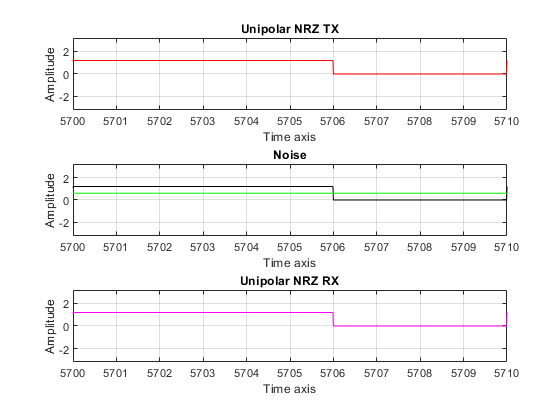

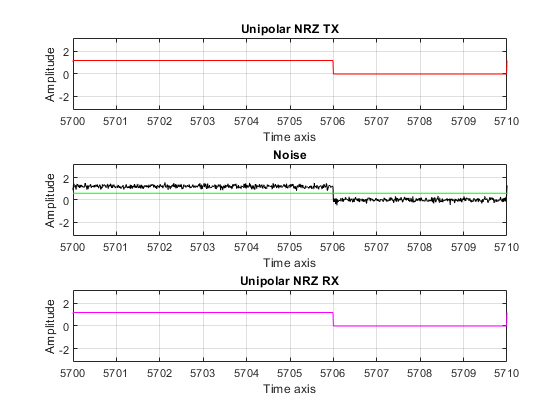

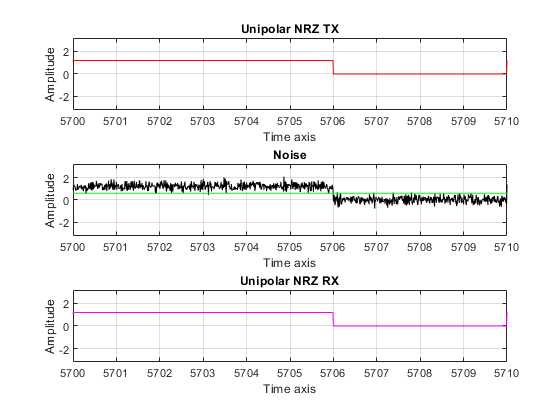

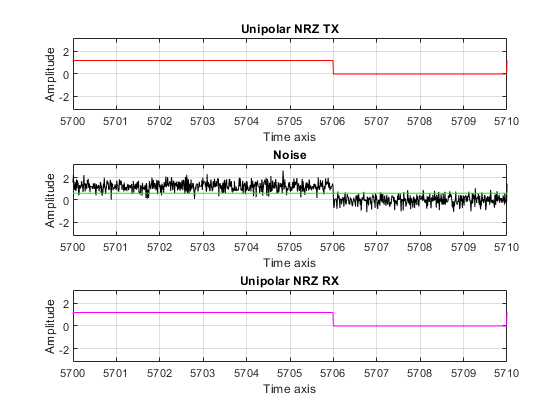

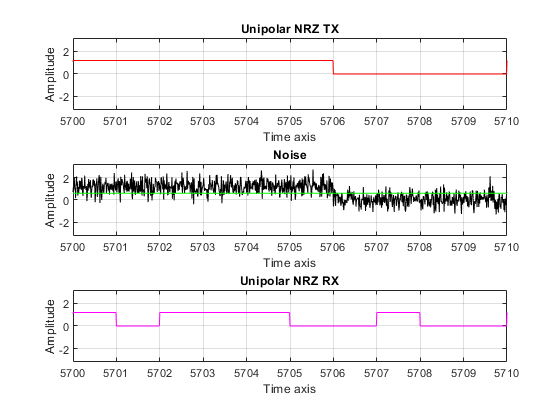

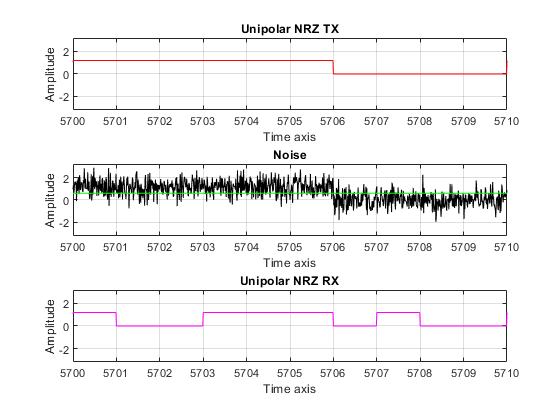

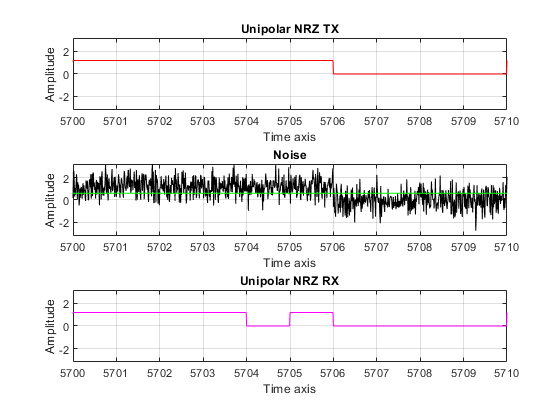

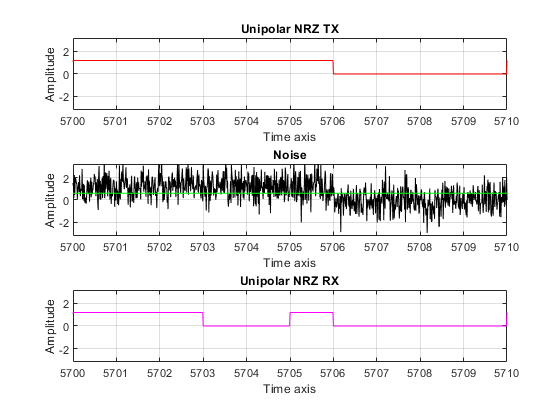

for unn=1:10 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Modify the amp. %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:length(LINE_CODE)                      %loop to take all values in LINE_CODE array 
    if LINE_CODE(i)==1                           %if current value ==1  
        data_UP_NRZ(i)=VCC;                      %convert it to vcc and store it in data array
    else                                         %else "cuurent value ==0"
        data_UP_NRZ(i)=GND;                      %convert it to GND and store it in data array
    end                                          %end if condition
end                                              %end for loop
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% sampling data to be UP-NRZ %%%%%%%%%%%%%%%%%%%%%%%%%%
i=1;                                             %intialization i to be 1 
for j=1:length(t)                                %for loop in time axis 
    if t(j)<i                                    %if t(index)<i "counter"
        UP_NRZ(j)=data_UP_NRZ(i);                %store the same bit 100 times in UP_NRZ array
    else                                         %after 100 times, take the next bit
        i=i+1;                                   %next bit
        UP_NRZ(j)=data_UP_NRZ(i);                %make all bits repeated 100 times exactly
    end                                          %end if condition
end                                              %end for loop 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TX-SIGNAL"UP-NRZ" %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(unn)                                        %UP_NRZ figure
subplot(3,1,1)                                   %to plot 3 figure
plot(t,UP_NRZ,'r');                              %plot TX signal "stream of 10k bits"
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);    %To improve the overall shape
xlabel('Time axis');                             %x-axis
ylabel('Amplitude');                             %y-axis
title('Unipolar NRZ TX');                        %title
grid on;                                         %grid on
xlim([5700 5710])                            %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ADD NOISE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
NOISE_UP_NRZ = UP_NRZ +sigma(unn)*randn(size(UP_NRZ));%Add noise to simulate received waveform
figure(unn)                                             %UP_NRZ figure
subplot(3,1,2)                                        %to plot 3 figure
plot(t,NOISE_UP_NRZ,'black',t,threshold_UP,'g')                          %plot NOISE signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);         %To improve the overall shape
xlabel('Time axis');                                  %x-axis
ylabel('Amplitude');                                  %y-axis
title('Noise');
grid on;                                              %grid on
xlim([5700 5710])                                 %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RX %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;                                                  %modify the lenght of RX array
for i=50:100:length(UP_NRZ)                           %take the mid bits value
    if NOISE_UP_NRZ(i)>threshold_UP                   %compare a bit with thershold "bit>thershold"
        for k=1:100                                   %loop to generate vcc one bit
            RX_UP_NRZ(k+c)=VCC;                       %put vcc value in rx array
        end                                           %end for loop
    else                                              %compare a bit with thershold "bit<thershold"
        for k=1:100                                   %loop to generate GND one bit
            RX_UP_NRZ(k+c)=GND;                       %put GND value in rx array
        end                                           %end for loop
    end                                               %end for condition
    c=c+100;                                          %to shift the index, which take the next value
end                                                   %end for loop
figure(unn)                                             %UP_NRZ figure
subplot(3,1,3)                                        %to plot 3 figure
plot(t,RX_UP_NRZ,'m')                                 %plot RX signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);         %To improve the overall shape
xlabel('Time axis');                                  %x-axis
ylabel('Amplitude');                                  %y-axis
title('Unipolar NRZ RX');                             %title
grid on;                                              %grid on
xlim([5700 5710])                                 %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
no_bit_error_UP_NRZ=0;                                %error number of bits "after transmitter"
for i=1:length(RX_UP_NRZ)                             %to take all value
    if(UP_NRZ(i)~=RX_UP_NRZ(i))                       %to compare between two array
        no_bit_error_UP_NRZ=no_bit_error_UP_NRZ+1;    %counter to count number bit error
    end                                               %end if condition
end                                                   %end fot loop
no_bit_error_UP_NRZ=no_bit_error_UP_NRZ/fs;           %normalize number bit error
a_n_bit_error_UP_NRZ(unn)=no_bit_error_UP_NRZ;        %create array to store number bit error each value of sigma 
BER_UP_NRZ(unn)=no_bit_error_UP_NRZ/num_of_bits;      %calculate BER in each case 
end                                                   %end loop of sigma

# `convert line code to UP-RZ:`

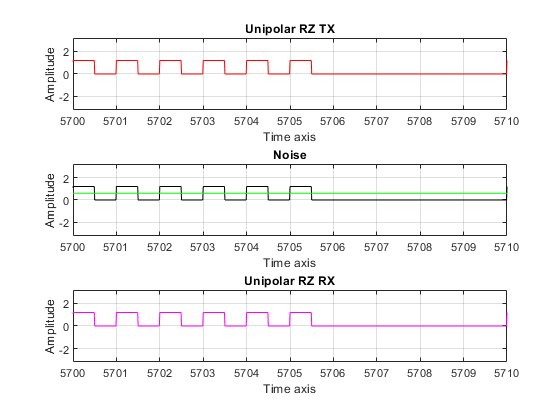

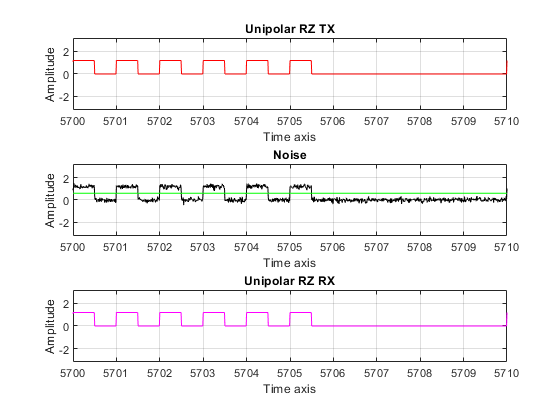

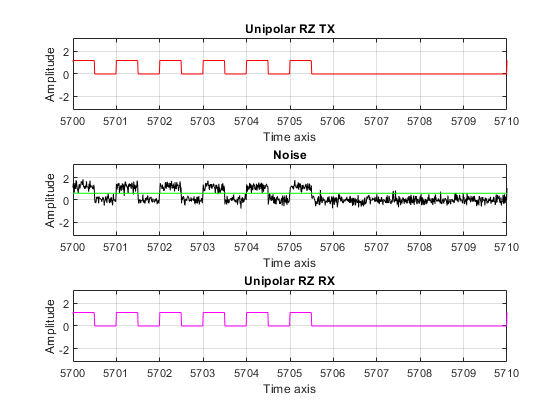

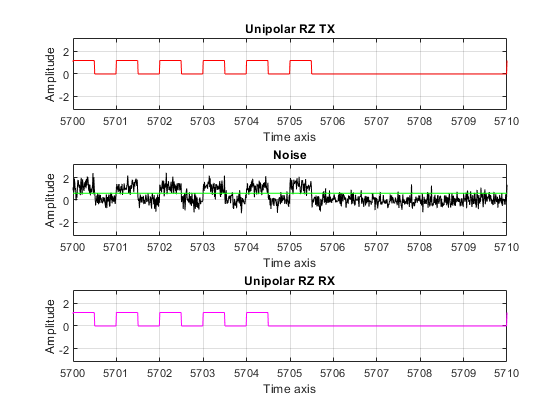

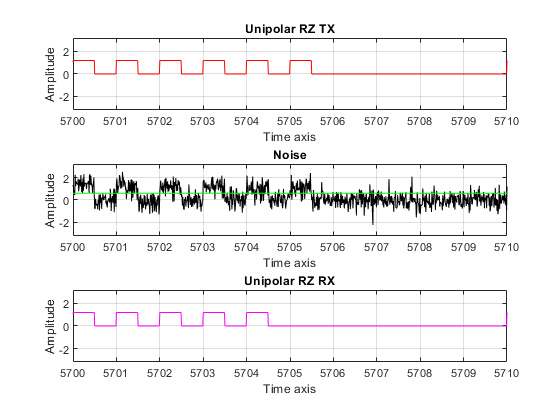

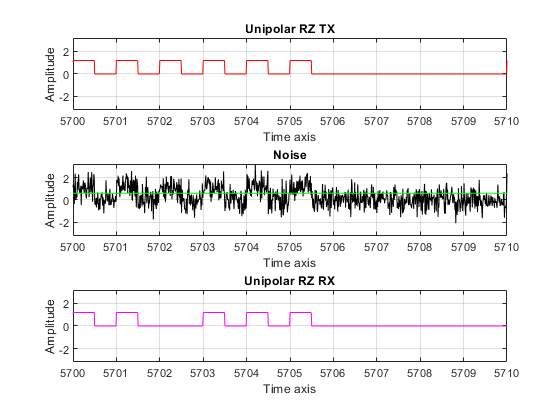

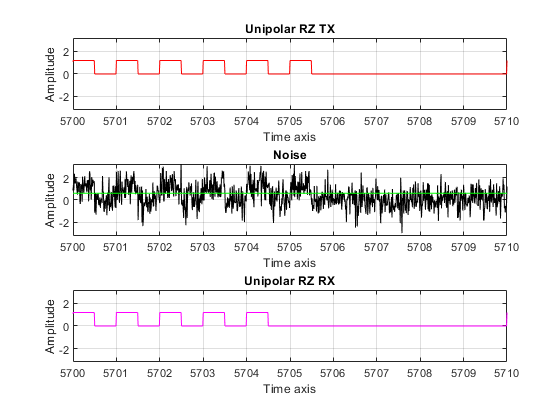

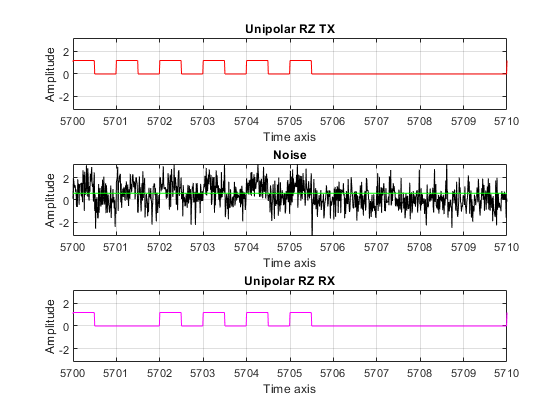

for unr=11:20 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Modify the amp. %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:length(LINE_CODE)                      %loop to take all values in LINE_CODE array 
    if LINE_CODE(i)==1                           %if current value ==1  
        data_UP_RZ(i)=VCC;                       %convert it to vcc and store it in data array
    else                                         %else "cuurent value ==0"
        data_UP_RZ(i)=GND;                       %convert it to GND and store it in data array
    end                                          %end if condition
end                                              %end for loop
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% sampling data to be UP-RZ %%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;
for i=1:length(data_UP_RZ)
    if data_UP_RZ(i)==VCC
        for q=1:50
            UP_RZ(q+c)=VCC;
            UP_RZ(q+50+c)=GND;
        end
    else
        for q=1:100
            UP_RZ(q+c)=GND;
        end
    end
    c=c+100;
end  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TX-SIGNAL"UP-RZ" %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(unr)                                        %UP_NRZ figure
subplot(3,1,1)                                   %to plot 3 figure
plot(t,UP_RZ,'r');                               %plot TX signal "stream of 10k bits"
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);    %To improve the overall shape
xlabel('Time axis');                             %x-axis
ylabel('Amplitude');                             %y-axis
title('Unipolar RZ TX');                         %title
grid on;                                         %grid on
xlim([5700 5710])                            %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ADD NOISE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
NOISE_UP_RZ = UP_RZ +sigma(unr-10)*randn(size(UP_RZ));   %Add noise to simulate received waveform
figure(unr)                                             %UP_RZ figure
subplot(3,1,2)                                        %to plot 3 figure
plot(t,NOISE_UP_RZ,'black',t,threshold_UP,'g')                           %plot NOISE signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);         %To improve the overall shape
xlabel('Time axis');                                  %x-axis
ylabel('Amplitude');                                  %y-axis
title('Noise');
grid on;                                              %grid on
xlim([5700 5710])                                 %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RX %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;                                                  %modify the lenght of RX array
for i=25:100:length(NOISE_UP_RZ)                      %take the mid bits value
    if NOISE_UP_RZ(i)>threshold_UP                    %compare a bit with thershold "bit>thershold"
        for q=1:50
            RX_UP_RZ(q+c)=VCC;
            RX_UP_RZ(q+50+c)=GND; 
        end                                           %end for loop
    else                                              %compare a bit with thershold "bit<thershold"
        for q=1:100                                   %loop to generate GND one bit
            RX_UP_RZ(q+c)=GND;                        %put GND value in rx array
        end                                           %end for loop
    end                                               %end for condition
    c=c+100;                                          %to shift the index, which take the next value
end                                                   %end for loop
figure(unr)                                             %UP_NRZ figure
subplot(3,1,3)                                        %to plot 3 figure
plot(t,RX_UP_RZ,'m')                                  %plot RX signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);         %To improve the overall shape
xlabel('Time axis');                                  %x-axis
ylabel('Amplitude');                                  %y-axis
title('Unipolar RZ RX');                              %title
grid on;                                              %grid on
xlim([5700 5710])                                 %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
no_bit_error_UP_RZ=0;                                %error number of bits "after transmitter"
for i=1:length(RX_UP_RZ)                             %to take all value
    if(UP_RZ(i)~=RX_UP_RZ(i))                        %to compare between two array
        no_bit_error_UP_RZ=no_bit_error_UP_RZ+1;     %counter to count number bit error
    end                                               %end if condition
end                                                   %end fot loop
no_bit_error_UP_RZ=no_bit_error_UP_RZ/fs*2;           %normalize number bit error
a_n_bit_error_UP_RZ(unr-10)=no_bit_error_UP_RZ;        %create array to store number bit error each value of sigma 
BER_UP_RZ(unr-10)=no_bit_error_UP_RZ/num_of_bits;      %calculate BER in each case 
end                                                   %end loop of sigma

# `%convert line code to P-NRZ:`

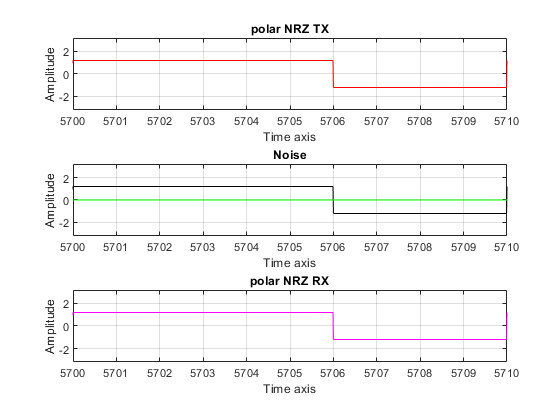

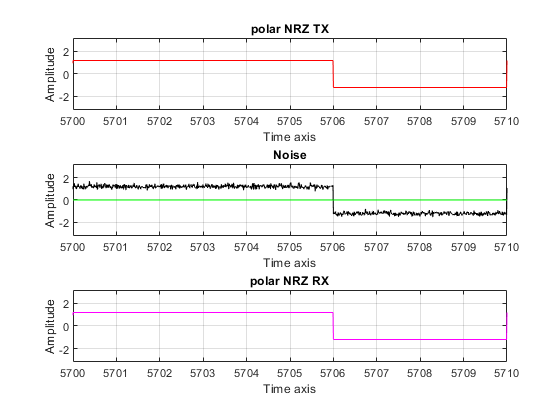

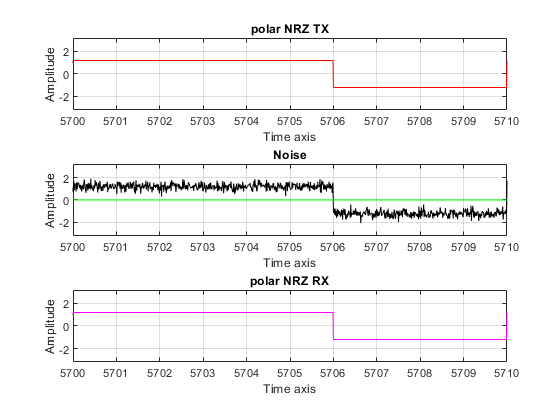

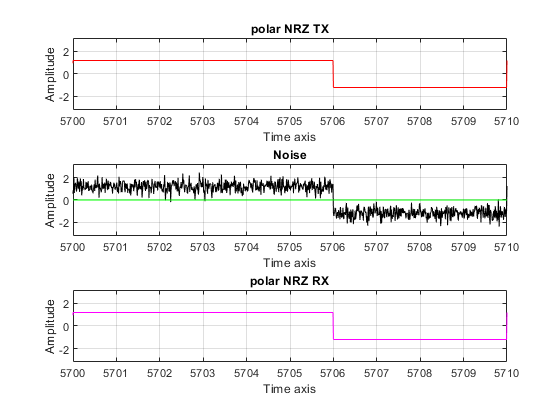

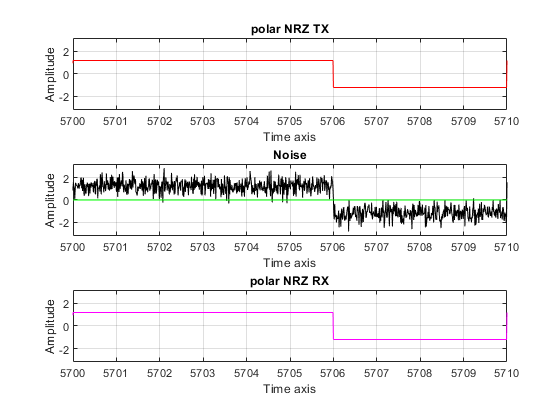

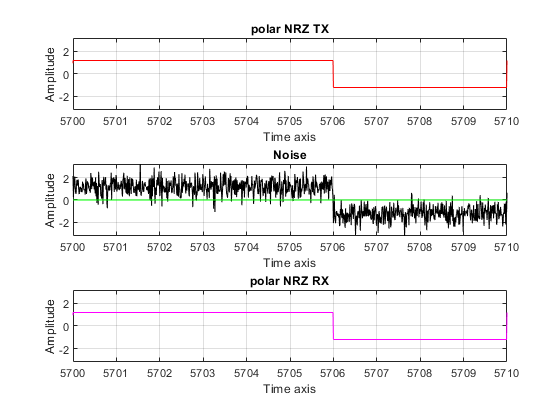

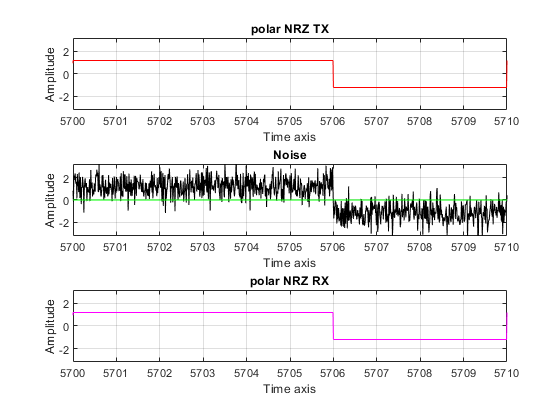

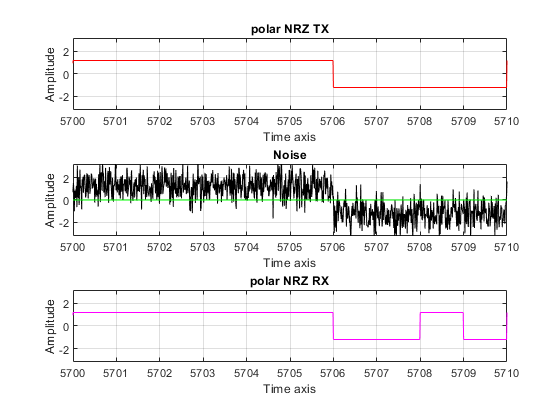

for pn=21:30                      
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Modify the amp.%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:length(LINE_CODE)      %loop to take all values in LINE_CODE array 
    if LINE_CODE(i)==1           %if current value ==1  
        data_P_NRZ(i)=VCC;       %convert it to vcc and store it in data array
    else                         %else "cuurent value ==0"
        data_P_NRZ(i)=VDD;       %convert it to VDD and store it in data array
    end                          %end if condition
end                              %end for loop
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%sampling data to be P-NRZ%%%%%%%%%%%%%%%%%%%%%%%%%%
i=1;                                 %intialization i to be 1 
for j=1:length(t)                    %for loop in time axis 
    if t(j)<i                        %if t(index)<i "counter"
        P_NRZ(j)=data_P_NRZ(i);      %store the same bit 100 times in P_NRZ array
    else                             %after 100 times, take the next bit
        i=i+1;                       %next bit
        P_NRZ(j)=data_P_NRZ(i);      %make all bits repeated 100 times exactly
    end                              %end if condition
end                                  %end for loop 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%TX-SIGNAL"P-NRZ"%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(pn)                                           %P_NRZ figure
subplot(3,1,1)                                       %to plot 3 figure
plot(t,P_NRZ,'r');                                   %plot TX signal "stream of 10k bits"
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);        %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('polar NRZ TX');                               %title
grid on;                                             %grid on
xlim([5700 5710])                                %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%ADD NOISE%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
NOISE_P_NRZ = P_NRZ +sigma(pn-20)*randn(size(P_NRZ));%Add noise to simulate received waveform
figure(pn)                                           %P_NRZ figure
subplot(3,1,2)                                       %to plot 3 figure
plot(t,NOISE_P_NRZ,'black',t,threshold_P,'g')       %plot NOISE signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);        %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('Noise');
grid on;                                             %grid on
xlim([5700 5710])                                %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RX %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;                                            %modify the lenght of RX array
for i=50:100:length(P_NRZ)                      %take the mid bits value
    if NOISE_P_NRZ(i)>threshold_P           %compare a bit with thershold "bit>thershold"
        for k=1:100                             %loop to generate vcc one bit
            RX_P_NRZ(k+c)=VCC;                  %put vcc value in rx array
        end                                     %end for loop
    else                                    %compare a bit with thershold "bit<thershold"
        for k=1:100                             %loop to generate VDD one bit
            RX_P_NRZ(k+c)=VDD;                  %put VDD value in rx array
        end                                     %end for loop
    end                                     %end conditions
    c=c+100;                                %to shift the index, which take the next value
end                                             %end for loop
figure(pn)                                      %P_NRZ figure
subplot(3,1,3)                                  %to plot 3 figure
plot(t,RX_P_NRZ,'m')                            %plot RX signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);   %To improve the overall shape
xlabel('Time axis');                            %x-axis
ylabel('Amplitude');                            %y-axis
title('polar NRZ RX');                          %title
grid on;                                        %grid on
xlim([5700 5710])                           %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
no_bit_error_P_NRZ=0;                            %error number of bits "after transmitter"
for i=1:length(RX_P_NRZ)                         %to take all value
    if(P_NRZ(i)~=RX_P_NRZ(i))                    %to compare between two array
        no_bit_error_P_NRZ=no_bit_error_P_NRZ+1; %counter to count number bit error
    end                                          %end if condition
end                                              %end fot loop
no_bit_error_P_NRZ=no_bit_error_P_NRZ/fs;        %normalize number bit error
a_n_bit_error_P_NRZ(pn-20)=no_bit_error_P_NRZ;   %create array to store number bit error each value of sigma 
BER_P_NRZ(pn-20)=no_bit_error_P_NRZ/num_of_bits; %calculate BER in each case 
end                                              %end loop of sigma

# `%convert line code to BP-RZ:`

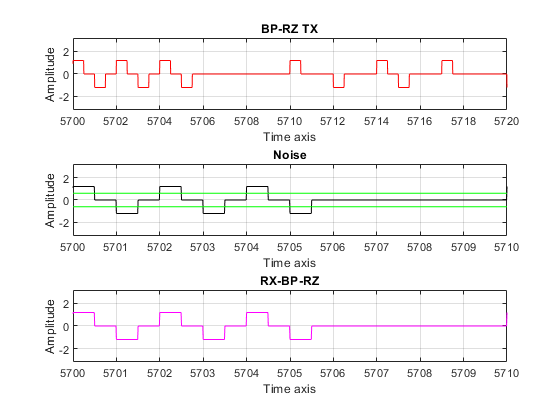

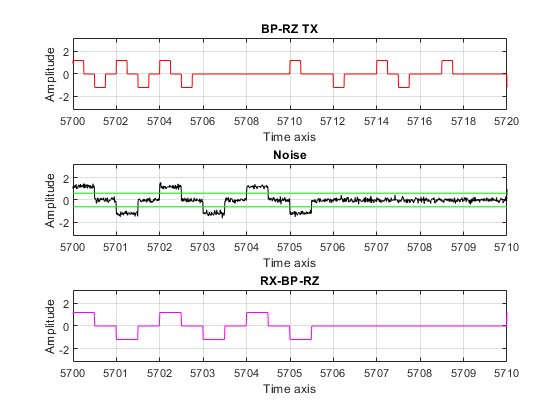

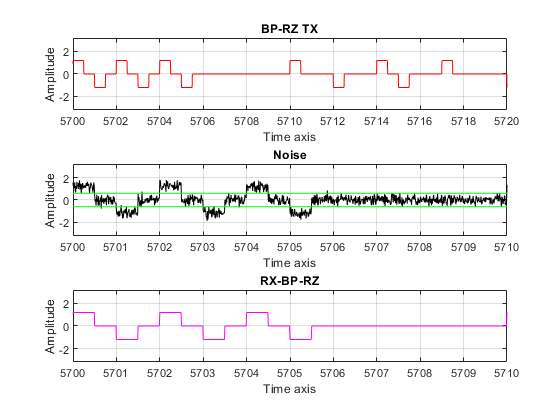

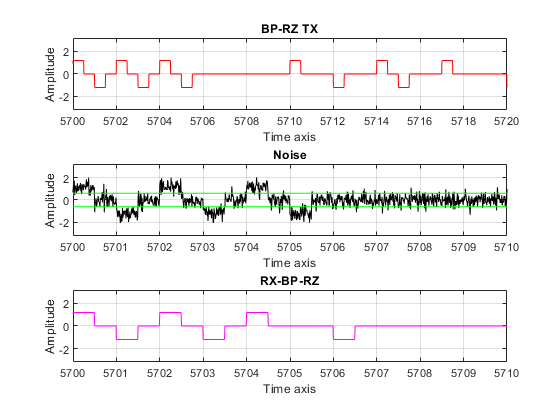

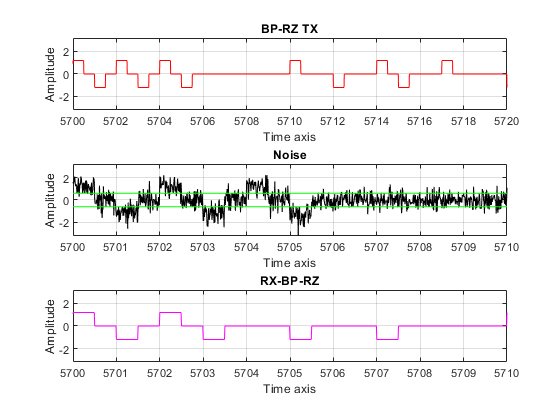

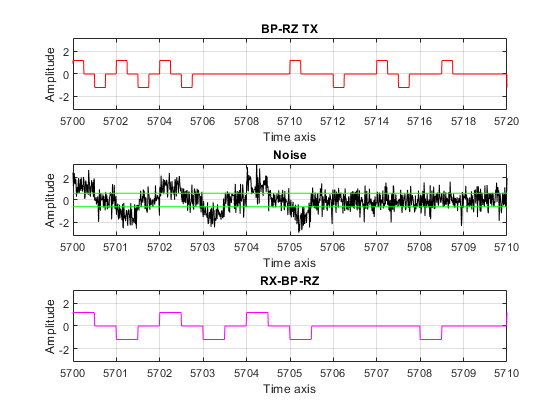

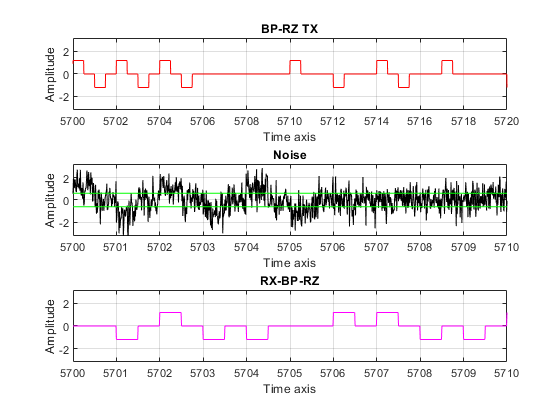

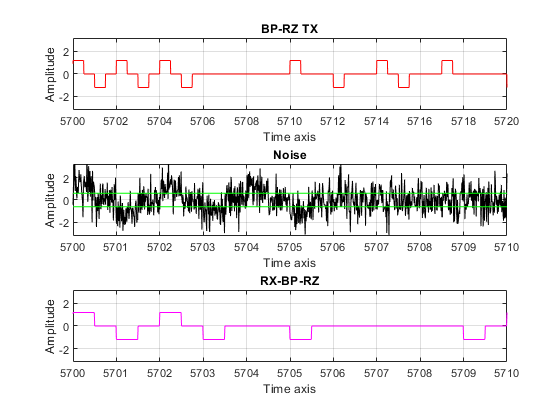

for bp=31:40       
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Modify the amp.%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
LINE_CODE_BP=LINE_CODE;
for w=1:length(LINE_CODE_BP)
    if LINE_CODE_BP(w)==1
       LINE_CODE_BP(w)=1.2;
       break;
    end
end
for i = 1:length(LINE_CODE_BP)     
    if LINE_CODE_BP(i)==0
        continue       
    elseif LINE_CODE_BP(i)==1.2 
        continue
    elseif LINE_CODE_BP(i)==1
        for e=(i-1):-1:1
            if LINE_CODE_BP(e)==VCC
               LINE_CODE_BP(i)=VDD;
               break
            elseif LINE_CODE_BP(e)==VDD
               LINE_CODE_BP(i)=VCC;
               break
            end 
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%sampling data to be P-NRZ%%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;
for i=1:length(LINE_CODE_BP)
    if LINE_CODE_BP(i)==VCC
        for q=1:50
            BP_RZ(q+c)=VCC;
            BP_RZ(q+50+c)=GND;
        end
    elseif LINE_CODE_BP(i)==VDD
        for q=1:50
            BP_RZ(q+c)=VDD;
            BP_RZ(q+50+c)=GND;
        end
    else
        for q=1:100
            BP_RZ(q+c)=GND;
        end
    end
    c=c+100;
end  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%TX-SIGNAL"BP_RZ"%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(bp)                                            %BP_RZ figure
subplot(3,1,1)                                       %to plot 3 figure
plot(t,BP_RZ,'r');                                   %plot TX signal "stream of 10k bits"
axis([0 length(LINE_CODE_BP) -(VCC+2) (VCC+2)]);     %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('BP-RZ TX');                                   %title
grid on;                                             %grid on
xlim([5700 5720])                                   %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%ADD NOISE%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
NOISE_BP_RZ = BP_RZ +sigma(bp-30)*randn(size(BP_RZ)); %Add noise to simulate received waveform
figure(bp)                                            %BP_RZ figure
subplot(3,1,2)                                       %to plot 3 figure
plot(t,NOISE_BP_RZ,'black',t,threshold1_BP,'g',t,threshold2_BP,'g')                          %plot NOISE signal
axis([0 length(LINE_CODE_BP) -(VCC+2) (VCC+2)]);     %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('Noise');
grid on;                                             %grid on
xlim([5700 5710])                                %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RX %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;                                                 %modify the lenght of RX array
for i=25:100:length(BP_RZ)                           %take the mid bits value
    if NOISE_BP_RZ(i)>threshold1_BP
        for q=1:50
            RX_BP_RZ(q+c)=VCC;
            RX_BP_RZ(q+50+c)=GND;
        end
    elseif NOISE_BP_RZ(i)<threshold2_BP
        for q=1:50
            RX_BP_RZ(q+c)=VDD;
            RX_BP_RZ(q+50+c)=GND;
        end
    else
        for q=1:100
            RX_BP_RZ(q+c)=GND;
        end
    end
    c=c+100;
end                                                  %end for loop
figure(bp)                                            %MANCHESTER figure
subplot(3,1,3)                                       %to plot 3 figure 
plot(t,RX_BP_RZ,'m')                                 %plot RX signal
axis([0 length(LINE_CODE_BP) -(VCC+2) (VCC+2)]);     %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('RX-BP-RZ');                                   %title
grid on;                                             %grid on
xlim([5700 5710])                                %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
no_bit_error_BP_RZ=0;                                      %error number of bits "after transmitter"
for i=1:length(RX_BP_RZ)                                   %to take all value
    if(BP_RZ(i)~=RX_BP_RZ(i))                              %to compare between two array
        no_bit_error_BP_RZ=no_bit_error_BP_RZ+1;           %counter to count number bit error
    end                                                    %end if condition
end                                                        %end fot loop
no_bit_error_BP_RZ=no_bit_error_BP_RZ/fs*2;        %normalize number bit error
a_n_bit_error_BP_RZ(bp-30)=no_bit_error_BP_RZ;    %create array to store number bit error each value of sigma 
BER_BP_RZ(bp-30)=no_bit_error_BP_RZ/num_of_bits;  %calculate BER in each case 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%BONUS%%%%%%%%%%%%%%%%%%%%%%%%
for i=1:length(RX_BP_RZ)
    if (RX_BP_RZ(i)== 1.2)
        break
    end
end

eee=0;
for BONUS=i:length(RX_BP_RZ)
    if RX_BP_RZ(BONUS)==GND 
        continue
    elseif RX_BP_RZ(BONUS)==VCC
        for back=(BONUS-100):-100:1
            if RX_BP_RZ(back)==VCC
                eee=eee+1;
                break
            elseif RX_BP_RZ(back)==VDD
                break
            elseif RX_BP_RZ(back)==GND
                continue
            end
        end
    elseif RX_BP_RZ(BONUS)==VDD
        for back=(BONUS-100):-100:1
            if RX_BP_RZ(back)==VDD
                eee=eee+1;  
                break
            elseif RX_BP_RZ(back)==VCC
                break
            elseif RX_BP_RZ(back)==GND
                continue
            end
        end
    end
end
error_detection(bp-30)= eee/50;
end

# `%convert line code to MANCHESTER:`      

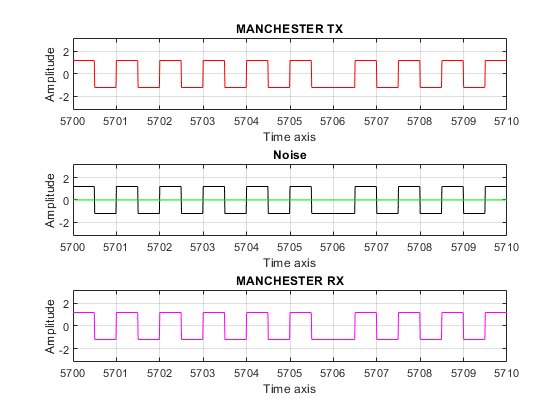

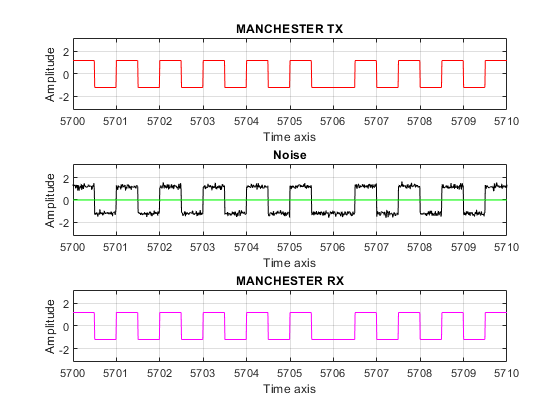

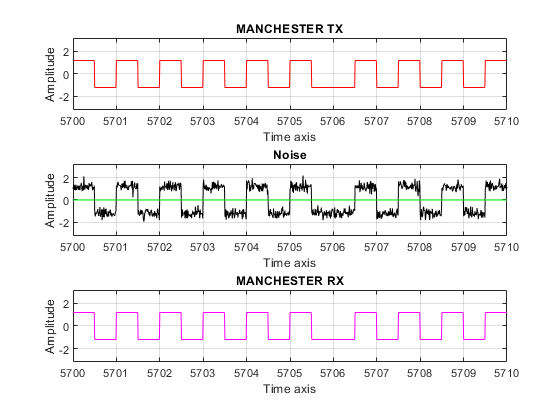

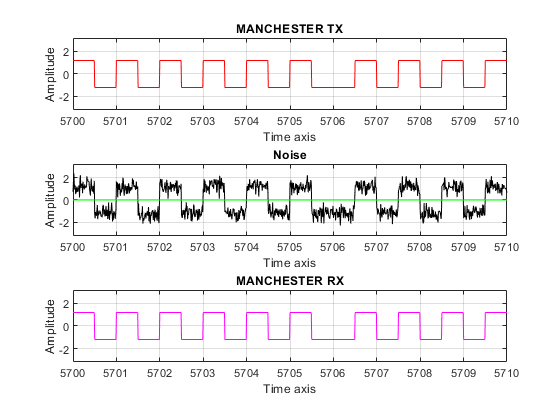

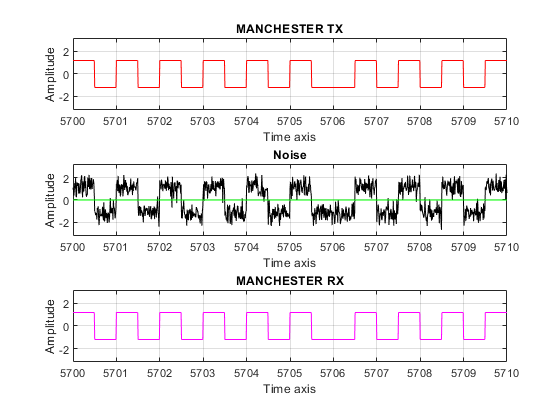

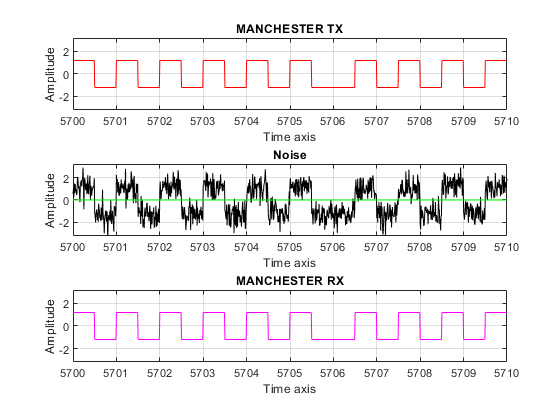

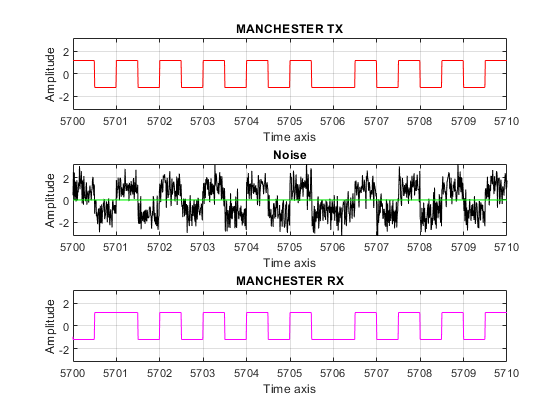

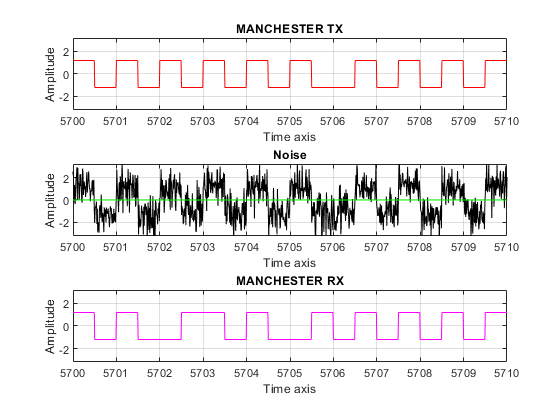

for m=41:50       
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Modify the amp.%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:length(LINE_CODE)      %loop to take all values in LINE_CODE array 
    if LINE_CODE(i)==1           %if current value ==1  
        data_MANCHESTER(i)=VCC;  %convert it to vcc and store it in data array
    else                         %else "cuurent value ==0"
        data_MANCHESTER(i)=VDD;  %convert it to VDD and store it in data array
    end                          %end if condition
end                              %end for loop
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% sampling data to be P-NRZ %%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;
for i=1:length(data_MANCHESTER)
    if data_MANCHESTER(i)==VCC
        for q=1:50
            MANCHESTER(q+c)=VCC;
            MANCHESTER(q+50+c)=VDD;
        end
    else
        for q=1:50
            MANCHESTER(q+c)=VDD;
            MANCHESTER(q+50+c)=VCC;
        end
    end
    c=c+100;
end  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%TX-SIGNAL"P-NRZ"%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(m)                                            %MANCHESTER figure
subplot(3,1,1)                                       %to plot 3 figure
plot(t,MANCHESTER,'r');                              %plot TX signal "stream of 10k bits"
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);        %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('MANCHESTER TX');                              %title
grid on;                                             %grid on
xlim([5700 5710])                                %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%ADD NOISE%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
NOISE_MANCHESTER = MANCHESTER +sigma(m-40)*randn(size(MANCHESTER));%Add noise to simulate received waveform
figure(m)                                            %MANCHESTER figure
subplot(3,1,2)                                       %to plot 3 figure
plot(t,NOISE_MANCHESTER,'black',t,threshold_Manchester,'g')                     %plot NOISE signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);        %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('Noise');
grid on;                                             %grid on
xlim([5700 5710])                                %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RX %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
c=0;                                                 %modify the lenght of RX array
for i=25:100:length(MANCHESTER)                      %take the mid bits value
    if NOISE_MANCHESTER(i)>threshold_Manchester  %compare a bit with thershold "bit>thershold"
       for q=1:50
           RX_MANCHESTER(q+c)=VCC;
           RX_MANCHESTER(q+50+c)=VDD;
       end
    else                                         %compare a bit with thershold "bit<thershold"
       for q=1:50
           RX_MANCHESTER(q+c)=VDD;
           RX_MANCHESTER(q+50+c)=VCC;
       end
    end                                          %end conditions
        c=c+100;                                     %to shift the index, which take the next value
end                                                  %end for loop
figure(m)                                            %MANCHESTER figure
subplot(3,1,3)                                       %to plot 3 figure
plot(t,RX_MANCHESTER,'m')                            %plot RX signal
axis([0 length(LINE_CODE) -(VCC+2) (VCC+2)]);        %To improve the overall shape
xlabel('Time axis');                                 %x-axis
ylabel('Amplitude');                                 %y-axis
title('MANCHESTER RX');                              %title
grid on;                                             %grid on
xlim([5700 5710])                                    %zoom in x-axis
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
no_bit_error_MANCHESTER=0;                                 %error number of bits "after transmitter"
for i=1:length(RX_MANCHESTER)                              %to take all value
    if(MANCHESTER(i)~=RX_MANCHESTER(i))                    %to compare between two array
        no_bit_error_MANCHESTER=no_bit_error_MANCHESTER+1; %counter to count number bit error
    end                                                    %end if condition
end                                                        %end fot loop
no_bit_error_MANCHESTER=no_bit_error_MANCHESTER/fs;        %normalize number bit error
a_n_bit_error_MANCHESTER(m-40)=no_bit_error_MANCHESTER;    %create array to store number bit error each value of sigma 
BER_MANCHESTER(m-40)=no_bit_error_MANCHESTER/num_of_bits;  %calculate BER in each case 
end                                                        %end loop of sigma

# `%log scale`

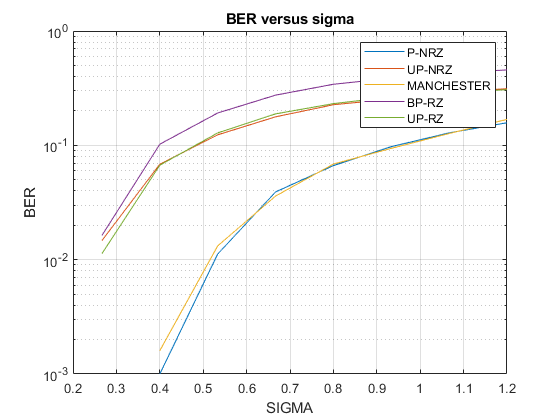

figure(51)
semilogy(sigma,BER_P_NRZ,sigma,BER_UP_NRZ,sigma,BER_MANCHESTER,sigma,BER_BP_RZ,sigma,BER_UP_RZ)
legend('P-NRZ','UP-NRZ','MANCHESTER','BP-RZ','UP-RZ')   %name
xlabel('SIGMA');                                %x-axis
ylabel('BER');                                  %y-axis
title('BER versus sigma');                      %title
grid on;                                        %grid on

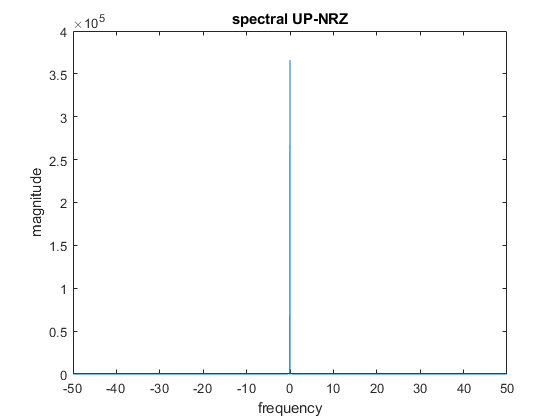

figure(52)
plot(f,(abs(fftshift(fft(UP_NRZ))).^2)/N)
xlabel('frequency');
ylabel('magnitude');
title('spectral UP-NRZ');

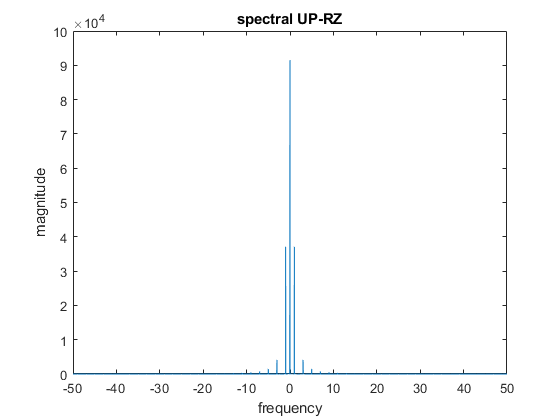


figure(53)
plot(f,(abs(fftshift(fft(UP_RZ))).^2)/N)
xlabel('frequency');
ylabel('magnitude');
title('spectral UP-RZ');

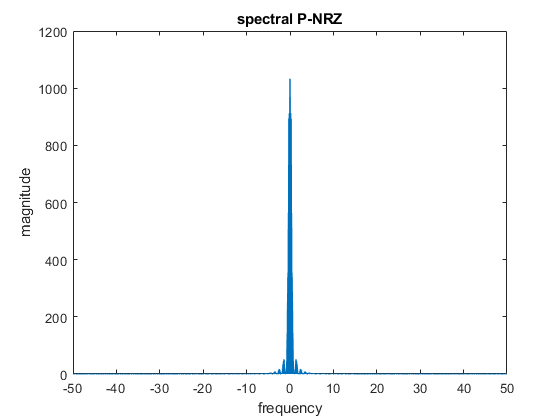


figure(54)
plot(f,(abs(fftshift(fft(P_NRZ))).^2)/N)
xlabel('frequency');
ylabel('magnitude');
title('spectral P-NRZ');

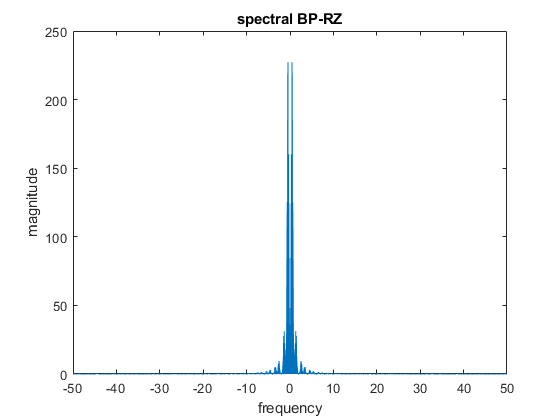


figure(55)
plot(f,(abs(fftshift(fft(BP_RZ))).^2)/N)
xlabel('frequency');
ylabel('magnitude');
title('spectral BP-RZ');

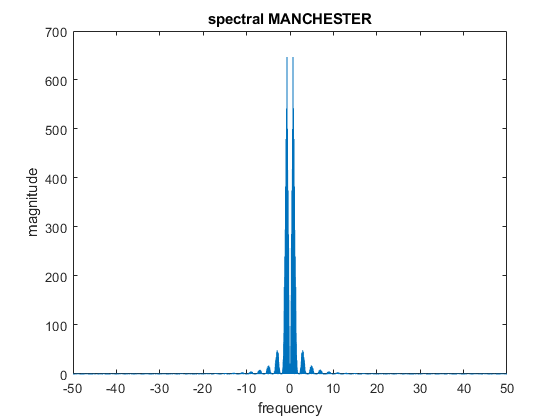


figure(56)
plot(f,(abs(fftshift(fft(MANCHESTER))).^2)/N)
xlabel('frequency');
ylabel('magnitude');
title('spectral MANCHESTER');

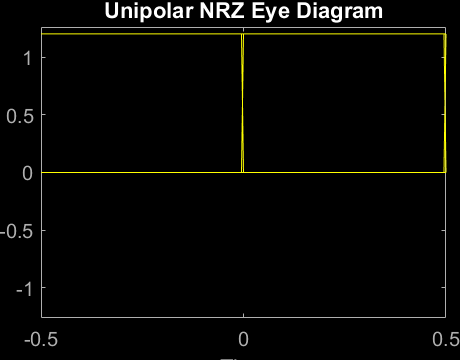

% Create eye diagram for unipolar nrz
figure(57);
eyediagram(UP_NRZ,200,1,0) ;
xlabel('Time');
ylabel('Amplitude');
title('Unipolar NRZ Eye Diagram');
set(gca, 'FontSize', 15);

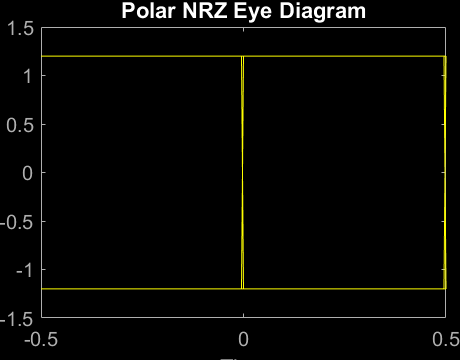


% Create eye diagram for Polar NRZ
figure(58);
eyediagram(P_NRZ,200,1,0) ;
xlabel('Time');
ylabel('Amplitude');
title('Polar NRZ Eye Diagram');
set(gca, 'FontSize', 15);

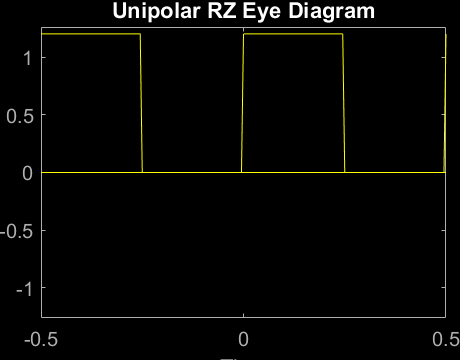


% Create eye diagram for Unipolar RZ
figure(59);
eyediagram(UP_RZ,200,1,0) ;
xlabel('Time');
ylabel('Amplitude');
title('Unipolar RZ Eye Diagram');
set(gca, 'FontSize', 15);

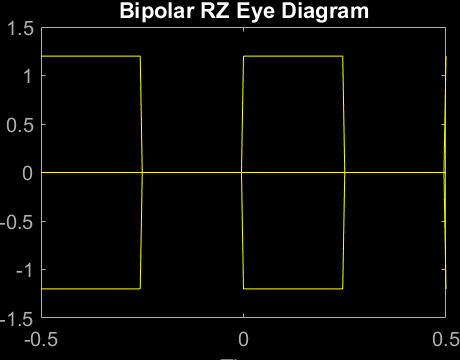


% Create eye diagram for Bipolar RZ
figure(60);
eyediagram(BP_RZ,200,1,0) ;
xlabel('Time');
ylabel('Amplitude');
title('Bipolar RZ Eye Diagram');
set(gca, 'FontSize', 15);

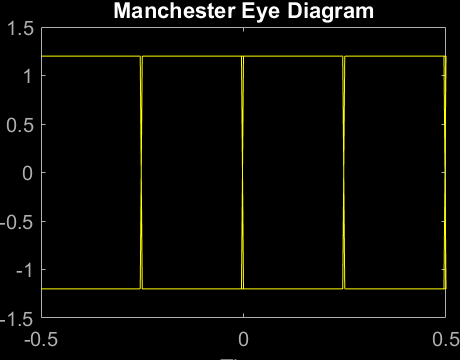


% Create eye diagram for Manchester
figure(61);
eyediagram(MANCHESTER,200,1,0) ;
xlabel('Time');
ylabel('Amplitude');
title('Manchester Eye Diagram');
set(gca, 'FontSize', 15);